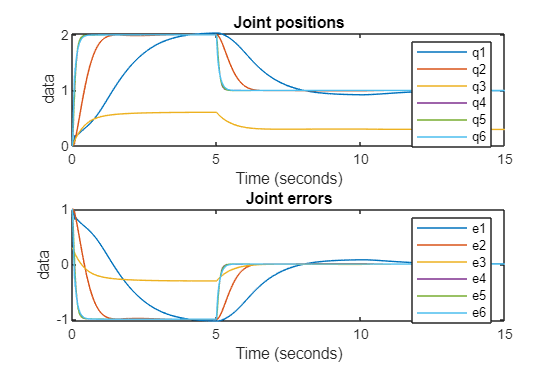

% Plot
out.q.Data(:,3) = out.q.Data(:,3) - 0.4318;
figure('Position', [270,140,750,500])
subplot(2,1,1)
plot(out.q)
title("Joint positions")
legend('q1','q2','q3','q4','q5','q6')

subplot(2,1,2)
plot(out.error)
title("Joint errors")
legend('e1','e2','e3','e4','e5','e6')

# Regulation

% PD Regulation with gravity compensation
q_dq_init = [0,0,0+0.4318,0,0,0,0,0,0,0,0,0];
qd = [1,1,0.3+0.4318,1,1,1];

Kp = diag([100,200,10,10,10,10]);
Kd = diag([20,100,10,10,10,10]);

% Iterative learning control

q_dq_init = [0,0,0+0.4318,0,0,0,0,0,0,0,0,0];
qd = [1,1,0.3+0.4318,1,1,1];

gamma = 10

gamma = 10


Kp = diag([10,100,10,10,10,10]);
Kd = diag([150,500,50,10,10,10]);

# Trajectory tracking

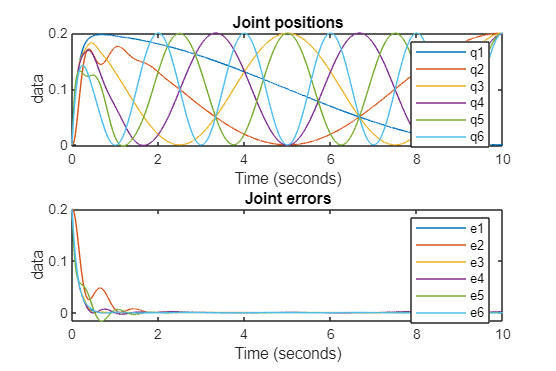

% Plot
out.q.Data(:,3) = out.q.Data(:,3) - 0.4318;
figure('Position', [270,140,750,500])
subplot(2,1,1)
plot(out.q)
title("Joint positions")
legend('q1','q2','q3','q4','q5','q6')

subplot(2,1,2)
plot(out.error)
title("Joint errors")
legend('e1','e2','e3','e4','e5','e6')

% Generate Trajectory

T = 0.001;

T = 1.0000e-03

t = 0:T:50;

q1_desired = 0.1 + 0.1*cos(0.1.*pi.*t);
q2_desired = 0.1 + 0.1*cos(0.2.*pi.*t);
q3_desired = 0.1 + 0.1*cos(0.4.*pi.*t) +0.4318;

q4_desired = 0.1 + 0.1*cos(0.6.*pi.*t);
q5_desired = 0.1 + 0.1*cos(0.8.*pi.*t);
q6_desired = 0.1 + 0.1*cos(1.*pi.*t);

dq1_desired = gradient(q1_desired)/T;
dq2_desired = gradient(q2_desired)/T;
dq3_desired = gradient(q3_desired)/T;
dq4_desired = gradient(q4_desired)/T;
dq5_desired = gradient(q5_desired)/T;
dq6_desired = gradient(q6_desired)/T;

ddq1_desired = gradient(dq1_desired)/T;
ddq2_desired = gradient(dq2_desired)/T;
ddq3_desired = gradient(dq3_desired)/T;
ddq4_desired = gradient(dq4_desired)/T;
ddq5_desired = gradient(dq5_desired)/T;
ddq6_desired = gradient(dq6_desired)/T;

q_desired = [t.', q1_desired.', q2_desired.', q3_desired.', q4_desired.', q5_desired.', q6_desired.'];
dq_desired = [t.', dq1_desired.', dq2_desired.', dq3_desired.', dq4_desired.', dq5_desired.', dq6_desired.'];
ddq_desired = [t.', ddq1_desired.', ddq2_desired.', ddq3_desired.', ddq4_desired.', ddq5_desired.', ddq6_desired.'];

q_dq_init = [0,0,0+0.4318,0,0,0,0,0,0,0,0,0];

% Feedback linearization / computed torque
Kp = 800*eye(6);
Kd = 100*eye(6);

% Inverse dynamics compensation

% ud = zeros(size(q_desired));
% ud(:,1) = q_desired(:,1);
% for i=1:size(q_desired, 1)
%     ud(i,2:7) = M_fun(q_desired(i,2:7))*ddq_desired(i,2:7).' + ...
%         C_fun(q_desired(i,2:7),dq_desired(i,2:7)) + G_fun(q_desired(i,2:7),9.81);
% end
% save("ud_IDC","ud")

load("ud_IDC.mat")

Kp = diag([800,1000,800,800,800,800]);
Kd = diag([100,500,100,100,100,100]);

% Adaptive control

Kp = diag([800,1500,800,800,800,800]);
Kd = diag([100,500,100,100,100,100]);
Lambda = Kd\Kp;

Kpi = 0.05*eye(35);

% real_coef = double(subs(Theta, params_sym, params_num))
coef_init = zeros(1,35);

% Impedance control

% Cartesian trajectory

T = 0.001

T = 1.0000e-03

t = 0:T:50;

x1_desired = 0.1*cos(0.5.*pi.*t);
x2_desired = 0.1*sin(0.5.*pi.*t);
x3_desired = -1.*ones(size(t));

% x1_desired = 0*ones(size(t));
% x2_desired = 0*ones(size(t));
% x3_desired = 0.0065*ones(size(t));

x4_desired = -pi/2*ones(size(t));
x5_desired = pi/2*ones(size(t));
x6_desired = -pi/2*ones(size(t));

dx1_desired = gradient(x1_desired)/T;
dx2_desired = gradient(x2_desired)/T;
dx3_desired = gradient(x3_desired)/T;
dx4_desired = gradient(x4_desired)/T;
dx5_desired = gradient(x5_desired)/T;
dx6_desired = gradient(x6_desired)/T;

ddx1_desired = gradient(dx1_desired)/T;
ddx2_desired = gradient(dx2_desired)/T;
ddx3_desired = gradient(dx3_desired)/T;
ddx4_desired = gradient(dx4_desired)/T;
ddx5_desired = gradient(dx5_desired)/T;
ddx6_desired = gradient(dx6_desired)/T;

x_desired = [t.', x1_desired.', x2_desired.', x3_desired.', x4_desired.', x5_desired.', x6_desired.'];
dx_desired = [t.', dx1_desired.', dx2_desired.', dx3_desired.', dx4_desired.', dx5_desired.', dx6_desired.'];
ddx_desired = [t.', ddx1_desired.', ddx2_desired.', ddx3_desired.', ddx4_desired.', ddx5_desired.', ddx6_desired.'];

q_dq_init = [0,0,0.4318,0,0,0,0,0,0,0,0,0];

Km = diag([100,3000,100,50,20,10]);
Dm = diag([10,400,50,20,5,5]);
% Km = 100*eye(6);
% Dm = 10*eye(6);
Fa = zeros(size(x_desired));
Fa(5/T:size(Fa,1),4) = 20;
Fa(:,1) = t.';

% Plot
out.q.Data(:,3) = out.q.Data(:,3) - 0.4318;

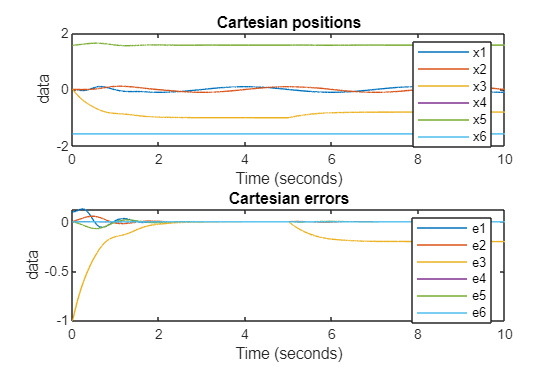

figure('Position', [270,140,750,500])
subplot(2,1,1)
plot(out.x)
title("Cartesian positions")
legend('x1','x2','x3','x4','x5','x6')

subplot(2,1,2)
plot(out.error)
title("Cartesian errors")
legend('e1','e2','e3','e4','e5','e6')

q_plot = resample(out.q,0:0.01:10)

  timeseries

  Common Properties:
            Name: 'q'
            Time: [1001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1001x6 double]
        DataInfo: 